%Preliminary variables
%Settings
testVolume = [4000, 4000, 1500]; %x, y, z; in millimetres
testInterval = 100; %gap between test positions, in millimetres
inlierThreshold =8;%0.00001;%5;
methodName = 'KneipN';
rtRounding = 10; %4 decimal places
noise_pix =5;
filter =10; %show results where error is greater than this value (in mm)

testPositions = [];
testCorners = [];
imageCorners = [];
error = [];
p3pResult = struct();

%Camera position
K = [1109 0 640; 0 1109 360; 0 0 1]; %virtual camera
imageSize = [1280, 720];
cameraRt = [0 -1 0 0;
            -1 0 0 0;
            0 0 -1 1510];
%cameraPos = [0, 0, 5000];
%cameraOrient =[-90,0 ,180];
%cameraR = eul2rotm(deg2rad(cameraOrient), "ZYX");
%camerat = transpose(cameraPos);
%cameraRt = [cameraR camerat];

%Configure test object: checkerboard
checkerSize = [5, 8];
checkerEdge = 31; %mm

%Generate test object positions
counter = 1;
numRows = ceil(testVolume(2)/testInterval);
numColumns = ceil(testVolume(1)/testInterval);
numLayers = floor(testVolume(3)/testInterval);

for x=0:numColumns
    for y=0:numRows
        for z=0:numLayers
            xPos = (x-(numColumns/2))*testInterval;
            yPos = (y-(numRows/2))*testInterval;
            zPos = z*testInterval;
            testPositions(:, counter)=[xPos; yPos; zPos];
            counter = counter+1;

        end
    end
end
%testPositions = transpose([0,0,0; 300, 300, 0; 600,600, 0; 300, 600, 0; 600, 300, 0; 600, -600, 0])
%testPositions =[[0, 0, 0];  [0,300,0]; [0, (-300), 0]; [300, 0, 0]; [-300, 0, 0]];

%testPositions = [0, (-300), 0];
%testPositions = transpose(testPositions)
numTestCases = size(testPositions, 2);

%Generate corners for each test object
for i=1:numTestCases
    boardPosition = transpose(testPositions(:,i)*0.001);
    boardOrientation = [-180 0 90];
    Rt_B2W = worldObject.calcTransformB2W(boardOrientation, boardPosition);
    boardCorners = checker.calcCheckerEdgeCoords_W(checkerSize, checkerEdge, Rt_B2W);
    testCorners(:,:,i) = boardCorners;
end

%Project corners into camera frame
for i =1:numTestCases
    for n=1:size(testCorners,2)
        X_W = testCorners(:,n,i);
        x_i = p3pFuncs.projectPnt2Image(cameraRt, X_W, K);

        imageCorners(:,n,i) = x_i;
    end 
end

%Generate noise
noise = zeros(size(imageCorners));
if noise_pix > 0
    noise = (noise_pix *2).*rand(size(imageCorners)) - noise_pix;
end
%noise = noise_std * randn(size(imageCorners));
imageCorners_noisy = imageCorners + noise;



%Conduct P3P on each set of points
for i=1:numTestCases
    x_pnts_i = imageCorners_noisy(:,:,i);
    X_pnts_W = testCorners(:,:,i);
    p3pResult = runP3P(p3pResult, i, x_pnts_i, X_pnts_W, K, imageSize, checkerSize, inlierThreshold, rtRounding, methodName);
    calcRt = p3pResult.(methodName).Rt(:,:,i);
    error(:,i) = p3pFuncs.getOrientErrArr(cameraRt, calcRt);
end

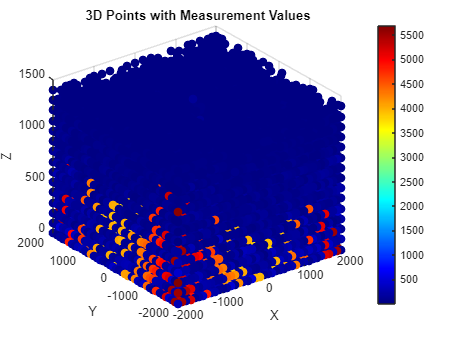


%plot results
%create a mask to filter out errors lower than 1 mm
mask = abs(error(2,:))>=filter;
testPositions_filtered = testPositions(:,mask);
error_filtered=error(:,mask);
% Create a 3D scatter plot with color representing the measurements
errorFig = figure;
colormap(jet);  % Use a colormap like 'jet' for a range of colors
errorPlot = scatter3(transpose(testPositions_filtered(1,:)), transpose(testPositions_filtered(2,:)), transpose(testPositions_filtered(3,:)), 50, transpose(error_filtered(2,:)), 'filled');  % 50 controls marker size
errorAx = errorFig.Children;
hold on
colorbar;  % Display a colorbar to interpret the measurement values

xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Points with Measurement Values');

% % % %Plot checkerboards - error checking
%   for i =1:numTestCases
%       X_pnts_W = testCorners(:,:,i);
%       p3pPlotting.addCheckerboard(errorAx, X_pnts_W);
%   end
% 
% % Plot image projections
%   for i =1:numTestCases
%       X_pnts_i = imageCorners(:,:,i);
%       p3pPlotting.addCheckerboard(errorAx, X_pnts_W);
%  end

% %Plot image projections
% % Plot image projections
%  for i =1:numTestCases
%       x_pnts_i = imageCorners(:,:,i);
%       p3pPlotting.plotImagePlanePnts(errorAx, x_pnts_i, cameraRt, K);
%  end
